# E20 Eksamen

## Opgave 1a)

clear

z = @(x,y) 12.0 + 313*y - 1466*y^2 + 7.69*x - 126*x.*y ...
           + 878*x.*y^2 - 2.42*x^2 + 34.1*x^2.*y - 213*x^2.*y^2;

x = 1:0.01:4;

y = 0.03:0.001:0.23;

zmax = 0;


for i = 1:length(x)
  for j = 1:length(y)
    zny = z(x(i),y(j));
    if zny > zmax
      xmaxz = x(i);   % "Notér" aktuel x-værdi i xmaxz
      ymaxz = y(j);   % "Notér" aktuel y-værdi i ymaxz
      zmax = zny;  % "Notér" aktuel z-værdi i zmax
    end
  end
end
xmaxz, ymaxz, zmax  % Skriv funden løsning

xmaxz = 2.1100

ymaxz = 0.1770

zmax = 35.0691

## Opgave 1b)

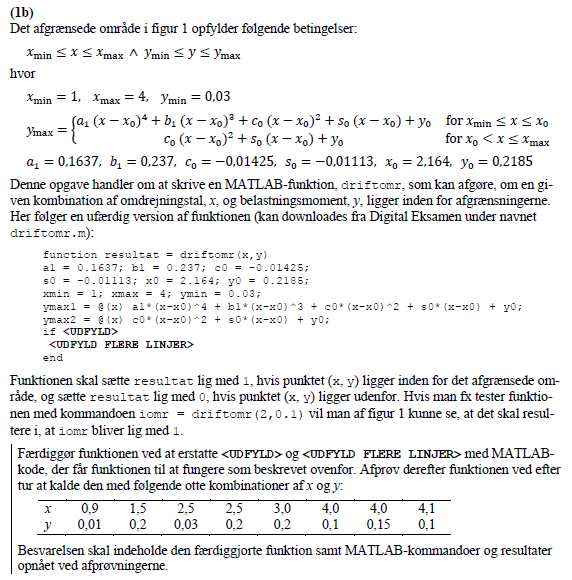

Her er den færdige funktion

Kaldt driftomr1, så jeg ved det er den der bruges

x = [0.9, 1.5, 2.5, 2.5, 3.0, 4, 4, 4.1];
y = [0.01, 0.2, 0.03, 0.2, 0.2, 0.1, 0.15, 0.1];

for i = 1:length(x)

    driftomr1(x(i), y(i))
end

ans = "Uden for området"

ans = "Uden for området"

ans = 1

ans = 1

ans = "Uden for området"

ans = 1

ans = 1

ans = "Uden for området"

## Opgave 2

Der står funktionen KAN løses vha. newtmult, hvilket jeg ikke gør

clear
format long
syms x y

z = 12.0 + 313*y - 1466*y^2 + 7.69*x - 126*x*y + 878*x*y^2 - 2.42*x^2 + 34.1*x^2*y - 213*x^2*y^2 - 34 == 0;
P = 104.7 * x*y - 40 == 0;



S = solve([z, P], [x,y]);

S = struct with fields:
    x: [4×1 sym]
    y: [4×1 sym]



vpa(S.x,5)

$$ans = \left(\begin{array}{c} 2.0805+3.8072\,\mathrm{i}\\ 2.0805-3.8072\,\mathrm{i}\\ 2.5777\\ 1.8223 \end{array}\right)$$

vpa(S.y,5)

$$ans = \left(\begin{array}{c} 0.042227-0.077272\,\mathrm{i}\\ 0.042227+0.077272\,\mathrm{i}\\ 0.14821\\ 0.20965 \end{array}\right)$$

## Opgave 3

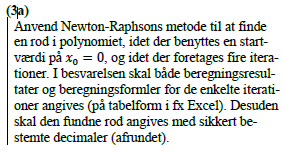

clear
syms x

p = @(x) 0.4*x^5 - x^4 - 6*x^3 + 2*x^2 + 16*x + 7;
dp = matlabFunction(diff(p, x));

x0 = 0;
iter = 4;

[root,ea,iter]=newtraph(p,dp,x0,iter);

root = vpa(root, 3)

$$root = -0.518$$

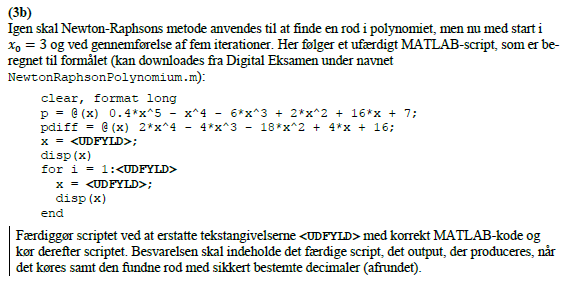

clear
format long
p = @(x) 0.4*x^5 - x^4 - 6*x^3 + 2*x^2 + 16*x + 7;
pdiff = @(x) 2*x^4 - 4*x^3 - 18*x^2 + 4*x + 16;

x = 3;

disp(x)

     3




for i = 1:5
  x = x - p(x)/pdiff(x);
  disp(x)
end

   2.090000000000000

   1.924121538104697

   1.908032816033752

   1.907874720973848

   1.907874705686683



clear
format long
p = @(x) 0.4*x^5 - x^4 - 6*x^3 + 2*x^2 + 16*x + 7;
pdiff = @(x) 2*x^4 - 4*x^3 - 18*x^2 + 4*x + 16;

p(-1)

ans =   -2.400000000000000


pdiff(-1)

ans =      0


Fordi den afledte giver 0, og da der skal divideres duer det ikke

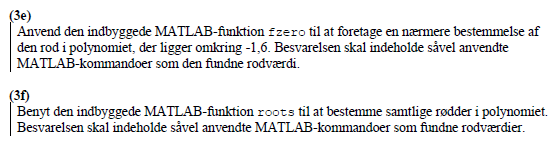

clear
format long
p = @(x) 0.4*x^5 - x^4 - 6*x^3 + 2*x^2 + 16*x + 7;
pdiff = @(x) 2*x^4 - 4*x^3 - 18*x^2 + 4*x + 16;

fzero(p, -1.6)

ans =   -1.550342596600663



clear
format long
p = @(x) 0.4*x^5 - x^4 - 6*x^3 + 2*x^2 + 16*x + 7;
pdiff = @(x) 2*x^4 - 4*x^3 - 18*x^2 + 4*x + 16;

roots([0.4 -1 -6 2 16 7])

ans =    4.963243089469575
   1.907874705686681
  -2.303215582431840
  -1.550342596600662
  -0.517559616123756


## Opgave 4

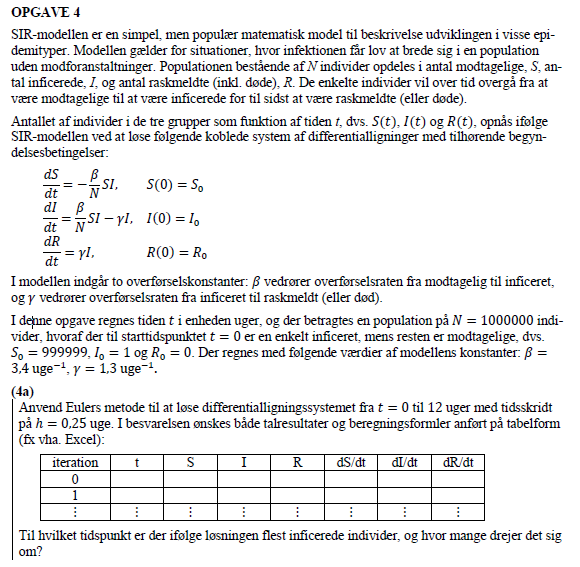

% Givne værdier
clear
format shortg

N = 1000000;
S0 = 999999;
I0 = 1;
R0 = 0;
beta = 3.4;
gamma = 1.3

gamma =           1.3



t = [0, 12]; % uger
h = 0.25;    % Skridt

% Startbetingelser
Sbs = [S0, I0, R0]

Sbs =       999999           1           0



% Her er de 3 liginger koblet sammen. Rækkefølgen har betydning


dYdt = @(t, Y) [-beta/N*Y(1)*Y(2), beta/N*Y(1)*Y(2) - gamma*Y(2), gamma*Y(2)]

dYdt = function_handle with value:
    @(t,Y)[-beta/N*Y(1)*Y(2),beta/N*Y(1)*Y(2)-gamma*Y(2),gamma*Y(2)]


[t, Y] = eulsys(dYdt,t, Sbs,h);

S = Y(:, 1);
I = Y(:, 2);
R = Y(:, 3);

disp(table(t, S, I, R, 'VariableNames',{'t, uger', 'S', 'I', 'R'}))

    t, uger        S             I             R     
    _______    __________    __________    __________

         0          1e+06             1             0
      0.25          1e+06         1.525         0.325
       0.5          1e+06        2.3256       0.82062
      0.75     9.9999e+05        3.5466        1.5765
         1     9.9999e+05        5.4085        2.7291
      1.25     9.9999e+05        8.2479        4.4868
       1.5     9.9998e+05        12.578        7.1674
      1.75     9.9997e+05        19.181        11.255
         2     9.9995e+05        29.251        17.489
      2.25     9.9993e+05        44.606        26.996
       2.5     9.9989e+05        68.022        41.493
      2.75     9.9983e+05        103.73          63.6
         3     9.9974e+05        158.17        97.311
      3.25     9.9961e+05        241.17        148.72


[I, t] =  max(I)

I =    2.7976e+05


t =     34


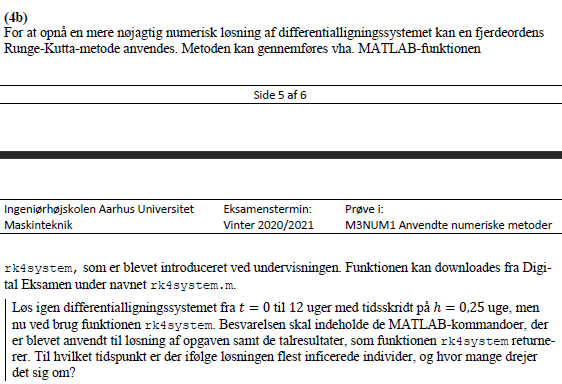

% Givne værdier
clear
format shortg

N = 1000000;
S0 = 999999;
I0 = 1;
R0 = 0;
beta = 3.4;
gamma = 1.3

gamma =           1.3



t = [0, 12]; % uger
h = 0.25;    % Skridt

% Startbetingelser
Sbs = [S0, I0, R0]

Sbs =       999999           1           0



% Her er de 3 liginger koblet sammen. Rækkefølgen har betydning


dYdt = @(t, Y) [-beta/N*Y(1)*Y(2), beta/N*Y(1)*Y(2) - gamma*Y(2), gamma*Y(2)]

dYdt = function_handle with value:
    @(t,Y)[-beta/N*Y(1)*Y(2),beta/N*Y(1)*Y(2)-gamma*Y(2),gamma*Y(2)]


[t, Y] = rk4system(dYdt,t, Sbs,h);

S = Y(:, 1);
I = Y(:, 2);
R = Y(:, 3);

disp(table(t, S, I, R, 'VariableNames',{'t, uger', 'S', 'I', 'R'}))

    t, uger        S             I             R     
    _______    __________    __________    __________

         0          1e+06             1             0
      0.25          1e+06        1.6901        0.4272
       0.5          1e+06        2.8564        1.1492
      0.75     9.9999e+05        4.8276        2.3695
         1     9.9999e+05         8.159        4.4318
      1.25     9.9998e+05        13.789        7.9173
       1.5     9.9996e+05        23.305        13.808
      1.75     9.9994e+05        39.385        23.764
         2     9.9989e+05         66.56        40.589
      2.25     9.9982e+05        112.48        69.022
       2.5     9.9969e+05        190.06        117.07
      2.75     9.9948e+05        321.12        198.25
         3     9.9912e+05         542.4        335.39
      3.25     9.9852e+05        915.81        566.99


[I, t] =  max(I)

I =    2.4933e+05


t =     28


# Funktioner

function resultat = driftomr1(x,y)

a1 = 0.1637; b1 = 0.237; c0 = -0.01425;

s0 = -0.01113; x0 = 2.164; y0 = 0.2185;

xmin = 1; xmax = 4; ymin = 0.03;

ymax1 = @(x) a1*(x-x0)^4 + b1*(x-x0)^3 + c0*(x-x0)^2 + s0*(x-x0) + y0;

ymax2 = @(x) c0*(x-x0)^2 + s0*(x-x0) + y0;

if (xmin <= x && x <= xmax) &&  (ymin <= y && y <= ymax1(x)) &&  (ymin <= y && y <= ymax2(x))
    resultat = 1;
else
    resultat = "Uden for området";
end

end


function [J,f] = jacobifunk(X)
x = X(1); y = X(2);
syms x y
z = 12.0 + 313*y - 1466*y^2 + 7.69*x - 126*x*y + 878*x*y^2 - 2.42*x^2 + 34.1*x^2*y - 213*x^2*y^2 - 34 ;
P = 104.7 * x*y - 40;


f = [z;P];
J = [jacobian(z);jacobian(P)];
end


function [x,f,ea,iter] = newtmult(func,x0,es,maxit)
% newtmult: Newton-Raphson root zeroes nonlinear systems
%   [x,f,ea,iter]=newtmult(func,x0,es,maxit):
%     uses the Newton-Raphson method to find the roots of
%     a system of nonlinear equations
% input:
%   func = name of function that returns f and J
%   x0 = initial guess
%   es = desired percent relative error (default = 0.0001%)
%   maxit = maximum allowable iterations (default = 50)
% output:
%   x = vector of roots
%   f = vector of functions evaluated at roots
%   ea = approximate percent relative error (%)
%   iter = number of iterations
if nargin<2, error('at least 2 input arguments required'), end
if nargin<3 || isempty(es), es = 0.0001; end
if nargin<4 || isempty(maxit), maxit = 50; end
iter = 0;
x = x0;
while 1
  [J,f] = func(x);
  dx = J\f;
  x = x-dx;
  iter = iter + 1;
  ea = 100*max(abs(dx./x));
  if iter>=maxit || ea<=es, break, end
end
end

function [root,ea,iter]=newtraph(func,dfunc,xr,es,maxit)
% newtraph: Newton-Raphson root location zeroes
%   [root,ea,iter]=newtraph(func,dfunc,xr,es,maxit):
%         uses Newton-Raphson method to find the root of func
% input:
%   func = name of function
%   dfunc = name of derivative of function
%   xr = initial guess
%   es = desired relative error (default = 0.0001%)
%   maxit = maximum allowable iterations (default = 50)
% output:
%   root = real root
%   ea = approximate relative error (%)
%   iter = number of iterations

if nargin<3,error('at least 3 input arguments required'),end
if nargin<4||isempty(es),es=0.0001; end
if nargin<5||isempty(maxit),maxit=50; end
iter = 0;
while 1
    xrold = xr;
    xr = xr - func(xr)/dfunc(xr);
    iter = iter + 1;
    if xr ~= 0, ea = abs((xr - xrold)/xr) * 100; end
    if ea <= es || iter >= maxit, break, end
end
root = xr;
end




function [t,Y] = eulsys(dYdt,tspan,Y0,h)
% eulsys: Euler solver for a system of ODEs
%   [t,Y] = eulsys(dYdt,tspan,Y0,h): uses Euler's
%     method to solve a system of first order 
%     differential equations.
% input:
%   dYdt = a function of (t,Y), where t is the independent
%     variable (scalar) and Y is a row vector of the 
%     dependent variables. The function should return a
%     row vector of derivatives of the independent
%     variables as given by the differential equations.
%   tspan = [ti, tf] where ti and tf = initial and
%     final values of independent variable
%   Y0 = initial value of dependent variables (row
%     vector)
%   h = step size
% output:
%   t = vector with values of the independent variable
%   Y = matrix with solution values of the dependent
%     variables. Each column represents one dependent 
%     variable
ti = tspan(1);
tf = tspan(2);
t = (ti:h:tf)';
n = length(t);
Y(1,:) = Y0;
for i = 1:n-1
  Y(i+1,:) = Y(i,:) + dYdt(t(i),Y(i,:))*h;
end
end


function [t,Y, iter] = rk4system(dYdt,tspan,Y0,h)
% rk4system: Fourth order Runge-Kutta solver for a system
%            of ODEs
%   [t,Y] = rk4system(dYdt,tspan,Y0,h): uses a fourth 
%     order Runge-Kutta method to solve a system of
%     first order differential equations.
% input:
%   dYdt = a function of (t,Y), where t is the independent
%     variable (scalar) and Y is a row vector of the 
%     dependent variables. The function should return a
%     row vector of derivatives of the independent
%     variables as given by the differential equations.
%   tspan = [ti, tf] where ti and tf = initial and
%     final values of independent variable
%   Y0 = initial value of dependent variables (row
%     vector)
%   h = step size
% output:
%   t = vector with values of the independent variable
%   Y = matrix with solution values of the dependent
%     variables. Each column represents one dependent 
%     variable
ti = tspan(1);
tf = tspan(2);
t = (ti:h:tf)';
n = length(t);
Y(1,:) = Y0;

iter = [0,];
for i = 1:n-1
    iter(end+1) = i;
  k1 = dYdt(t(i),Y(i,:));
  tmid1 = t(i) + h/2;
  Ymid1 = Y(i,:) + k1*h/2;
  k2 = dYdt(tmid1,Ymid1);
  tmid2 = t(i) + h/2;
  Ymid2 = Y(i,:) + k2*h/2;
  k3 = dYdt(tmid2,Ymid2);
  tend = t(i) + h;
  Yend = Y(i,:) + k3*h;
  k4 = dYdt(tend,Yend);
  phi = (k1 + 2*k2 + 2*k3 + k4)/6;
  Y(i+1,:) = Y(i,:) + phi*h;
end
iter = iter';
end







